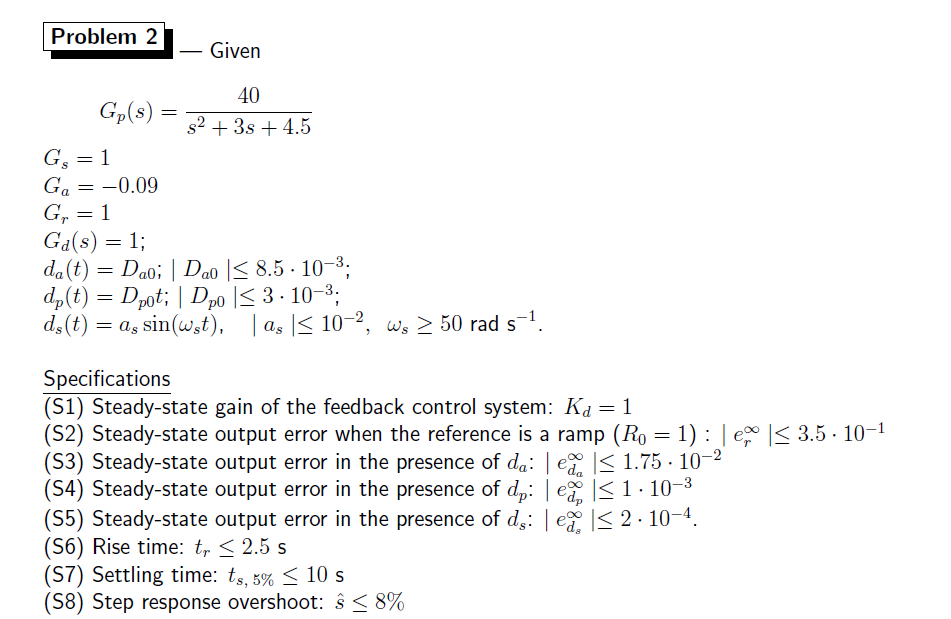

# Requirements Translation

% clear all

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



Gp=40/(s^2+3*s+4.5)

Gp =
 
        40
  ---------------
  s^2 + 3 s + 4.5
 
Continuous-time transfer function.



% zpk(Gp)
Gr=1 

Gr = 1

Ga=-0.09

Ga = -0.0900

Gd=1

Gd = 1

Gs=1

Gs = 1

Gf=1

Gf = 1

s_hat=0.08

s_hat = 0.0800

tr=2.5 %cambia

tr = 2.5000

ts=10

ts = 10

er=3.5*10^-1

er = 0.3500

e_da=1.75*10^-2

e_da = 0.0175

e_dp=1*10^-3

e_dp = 1.0000e-03

e_ds=2*10^-4

e_ds = 2.0000e-04

as=10^-2

as = 0.0100

Dao=8.5*10^-3

Dao = 0.0085

Dpo=3*10^-3

Dpo = 0.0030

ws=50

ws = 50

## S2

Kp=40/(3.391*1.327)

Kp = 8.8892

Kc=abs(1/(Kp*Ga*er))

Kc = 3.5713

## S3

Kc=Dao/(e_da*Gs*Gf*Ga*Kp) *10; %v=1 so no constrains here

## S4

Kc=abs(Dpo/(e_dp*Gs*Gf*Ga*Kp))

Kc = 3.7499

## S5

Mt_highfrequency=e_ds*Gs/(as)

Mt_highfrequency = 0.0200

Mt_highfrequency_dB=20*log10(Mt_highfrequency)

Mt_highfrequency_dB = -33.9794

wh=10^(Mt_highfrequency_dB/40)*ws

wh = 7.0711

wc=wh/2

wc = 3.5355

## S6

zeta=0.6266

zeta = 0.6266

tr_wc=(pi()-acos(zeta))*sqrt(sqrt(1+4*zeta^4)-2*zeta^2)/sqrt(1-zeta^2)

tr_wc = 2.0113

wc=tr_wc/tr

wc = 0.8045

## S7

ts_alfa_wc=-log(0.05)*sqrt(sqrt(1+4*zeta^4)-2*zeta^2)/zeta

ts_alfa_wc = 3.3337

wc=ts_alfa_wc/ts

wc = 0.3334

## S8

zeta=abs(log(s_hat))/sqrt(pi()^2+log(s_hat)^2)

zeta = 0.6266

Tp=1/(2*zeta*sqrt(1-zeta^2))

Tp = 1.0239

Tp_dB=20*log10(Tp)

Tp_dB = 0.2052

Sp=2*zeta*sqrt(2+4*zeta^2+2*sqrt(1+8*zeta^2))/(4*zeta^2-1+sqrt(1+8*zeta^2))

Sp = 1.3295

Sp_dB=20*log10(Sp)

Sp_dB = 2.4740

# Project

### 1.Sign of Kc

Analyzing the positive case of Kc we find that N is odd and the system results not stabilizable.

With Kc<0 however we can se that since N is even the system become stabilizable.

Kc=-4

Kc = -4

Gc=Kc/s;
L=(Gc*Gp*Gs*Gf*Ga)

L =
 
        -0.009025
  ---------------------
  s^4 + 3.3 s^3 + 2 s^2
 
Continuous-time transfer function.



wdes=1.3;
z=wdes/0.6;
L=L*(1+s/z);
zpk(L)

ans =
 
  -0.0041654 (s+2.167)
  --------------------
  s^2 (s+2.5) (s+0.8)
 
Continuous-time zero/pole/gain model.




% omega=logspace(-10,10,10000);
[num, den]=tfdata(L,'v')

num =          0         0         0   -0.0090   -0.0196


den =     2.1667    7.1500    4.3333         0         0


damp(L);

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -8.00e-01     1.00e+00       8.00e-01         1.25e+00    
 -2.50e+00     1.00e+00       2.50e+00         4.00e-01    


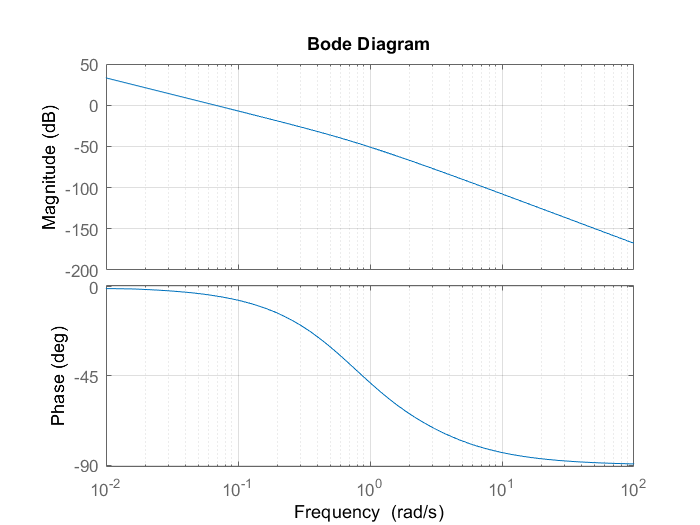

bode(L)
grid on

nyquist1(num,den) 

p =          0
         0
   -2.5000
   -0.8000


P = 0

P = number of Open loop poles in rhp


N = 0

N =  number of anti-clockwise encirclements


Z = 0

Z = number of closed loop poles in rhp


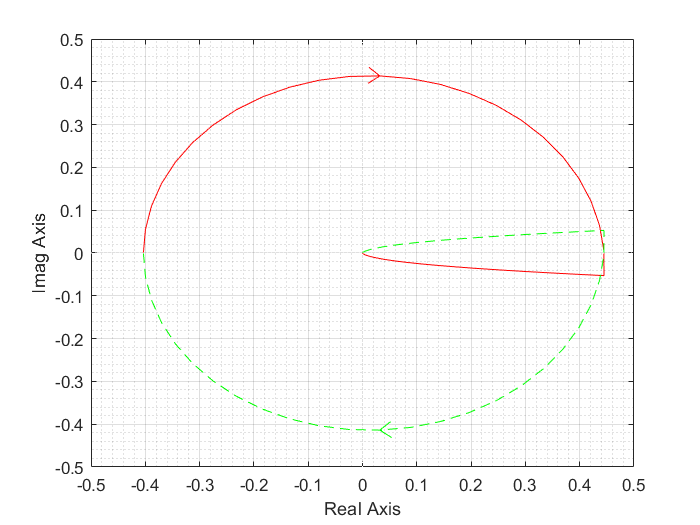

grid on
grid minor

To double check the correctness of the sign of Kc we can analyze the complementary sensitivity T(s) respose to the step.

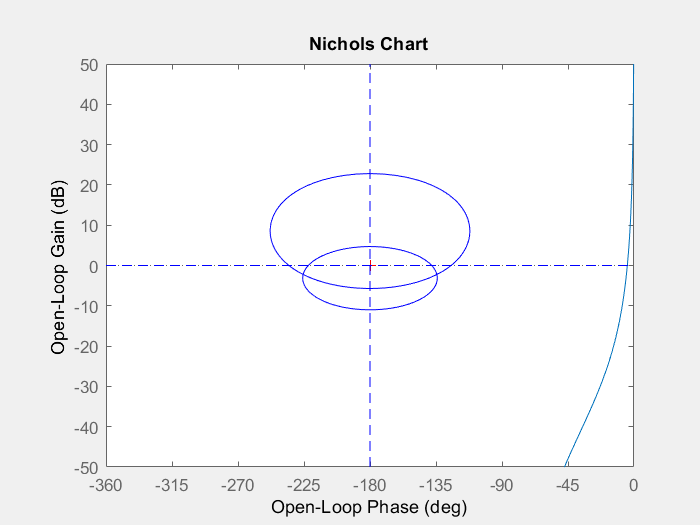

% T=minreal(L/(L+1))
% step(T)
% omega =logspace(-4,6,1000)
% nichols(L,omega)
% hold on
% myngridst(Tp,Sp)
% hold off
Rz=1;
R_lag=1;

% Rz=(1+s/1);
% R_lag=(1+s/(4.21*0.015))/(1+s/0.015);


Gc=Kc/s*Rz*R_lag;
su(L,Tp,Sp)

### 2. Wc_design selection

## S8 Plot tr wn zeta

syms tr_wn zeta ts_alfa_wc
assume(zeta,'positive')
tr_wc=(pi()-acos(zeta))*sqrt(sqrt(1+4*zeta^4)-2*zeta^2)/sqrt(1-zeta^2)

$$tr\_wc = \frac{\left(\pi -\mathrm{acos}\left(\zeta \right)\right)\,\sqrt{\sqrt{4\,\zeta^{4}+1}-2\,\zeta^{2}}}{\sqrt{1-\zeta^{2}}}$$

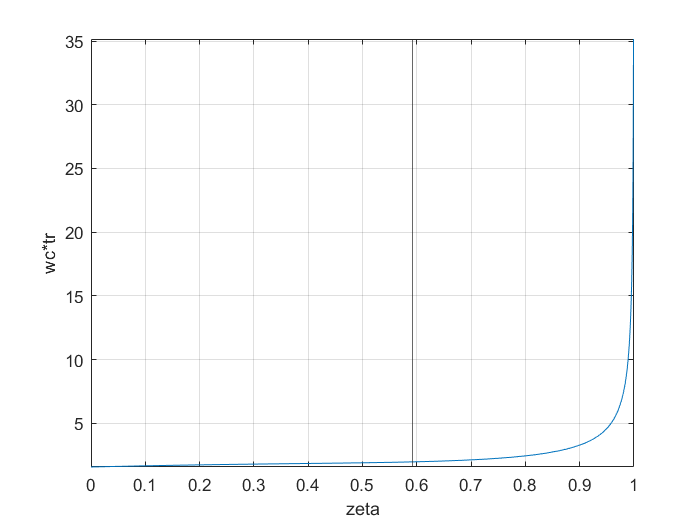

fplot(tr_wc,[0 1])
hold on
xline(0.5912)
grid on
xlabel('zeta')
ylabel('wc*tr')
hold off


assume(zeta,'positive')
ts_alfa_wc=-log(0.05)*sqrt(sqrt(1+4*zeta^4)-2*zeta^2)/zeta

$$ts\_alfa\_wc = \frac{6745789375439761\,\sqrt{\sqrt{4\,\zeta^{4}+1}-2\,\zeta^{2}}}{2251799813685248\,\zeta }$$

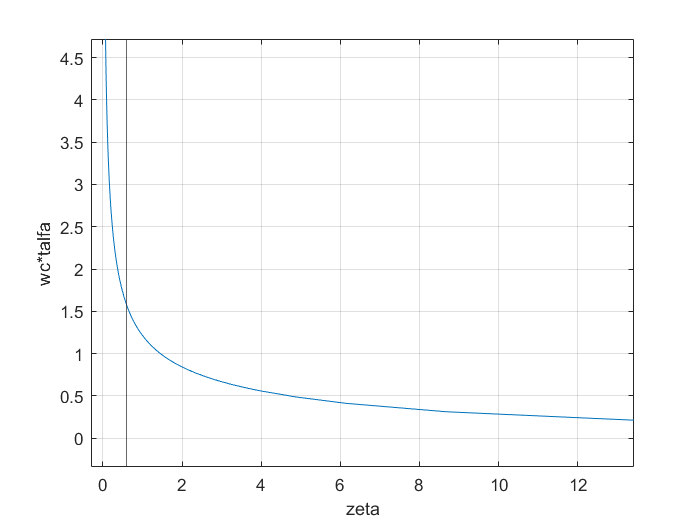

assume(zeta,'positive')
fplot(ts_alfa_wc,zeta)
hold on
xline(0.5912)
grid on
xlabel('zeta')
ylabel('wc*talfa')
xlim([-0.30 13.42])
ylim([-0.34 4.72])
hold off